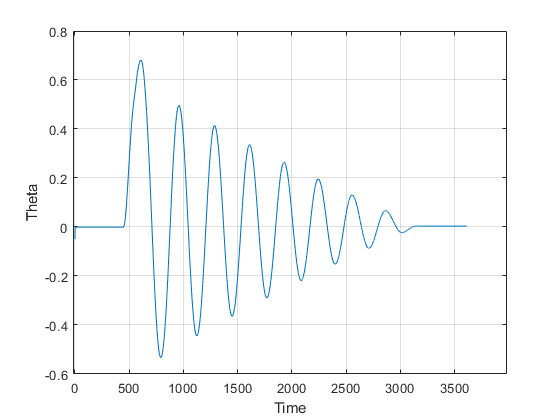

theta = dane_NN.signals(1).values + 1.58;
time = dane_NN.time;

figure
plot(theta)
xlabel('Time')
ylabel('Theta')
grid on

Zostaly podziolone dane zgodnie ze teorią przedstawioną na labolatoriach

y_begin_sample = 602;
y_end_sample = 2875;


training_data_input_1 = theta(y_begin_sample-2:y_end_sample-2)

training_data_input_1 =     0.6777
    0.6770
    0.6782
    0.6797
    0.6798
    0.6796
    0.6807
    0.6804
    0.6800
    0.6808


training_data_input_2 = theta(y_begin_sample-1:y_end_sample-1)

training_data_input_2 =     0.6770
    0.6782
    0.6797
    0.6798
    0.6796
    0.6807
    0.6804
    0.6800
    0.6808
    0.6802


training_data_output = theta(y_begin_sample:y_end_sample)

training_data_output =     0.6782
    0.6797
    0.6798
    0.6796
    0.6807
    0.6804
    0.6800
    0.6808
    0.6802
    0.6809



x_train = [training_data_input_1'; training_data_input_2']

x_train =     0.6777    0.6770    0.6782    0.6797    0.6798    0.6796    0.6807    0.6804    0.6800    0.6808    0.6802    0.6809    0.6801    0.6779    0.6780    0.6768    0.6768    0.6741    0.6738    0.6722    0.6703    0.6682    0.6661    0.6638    0.6626    0.6588    0.6574    0.6535    0.6502    0.6467    0.6449    0.6380    0.6365    0.6324    0.6283    0.6228    0.6196    0.6143    0.6076    0.6035    0.5996    0.5935    0.5893    0.5822    0.5782    0.5723    0.5656    0.5602    0.5538    0.5489
    0.6770    0.6782    0.6797    0.6798    0.6796    0.6807    0.6804    0.6800    0.6808    0.6802    0.6809    0.6801    0.6779    0.6780    0.6768    0.6768    0.6741    0.6738    0.6722    0.6703    0.6682    0.6661    0.6638    0.6626    0.6588    0.6574    0.6535    0.6502    0.6467    0.6449    0.6380    0.6365    0.6324    0.6283    0.6228    0.6196    0.6143    0.6076    0.6035    0.5996    0.5935    0.5893    0.5822    0.5782    0.5723    0.5656    0.5602    0.5538    0.548

% time = time(600:2873)
y_train = training_data_output'

y_train =     0.6782    0.6797    0.6798    0.6796    0.6807    0.6804    0.6800    0.6808    0.6802    0.6809    0.6801    0.6779    0.6780    0.6768    0.6768    0.6741    0.6738    0.6722    0.6703    0.6682    0.6661    0.6638    0.6626    0.6588    0.6574    0.6535    0.6502    0.6467    0.6449    0.6380    0.6365    0.6324    0.6283    0.6228    0.6196    0.6143    0.6076    0.6035    0.5996    0.5935    0.5893    0.5822    0.5782    0.5723    0.5656    0.5602    0.5538    0.5489    0.5426    0.5371


Następnie zostala wytrenowana siec neuronowa:

net = feedforwardnet(2, 'trainlm');
net = train(net, x_train, y_train);
view(net);
y_net = net(x_train);
perf = perform(net,y_train, y_net)  
net = feedforwardnet(2, 'trainlm');
net = train(net, x_train, y_train);

y_net = net(x_train);


sample_time = 0.01;
perf = perform(net,y_train, y_net)

perf = 3.8247e-06

gensim(net, sample_time)

ans = 'untitled1'

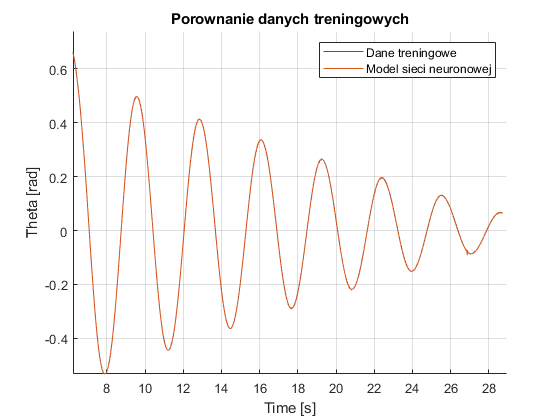

figure();
hold on
plot(time, y_train)
plot(time, y_net)
hold off
legend("Dane treningowe", 'Model sieci neuronowej')
xlabel('Time [s]')
ylabel('Theta [rad]')
title('Porownanie danych treningowych')
grid on


err = immse(y_train, y_net)

err = 3.8455e-06

err = y_net-y_train

err =    -0.0018   -0.0005    0.0013    0.0003   -0.0013    0.0013    0.0002   -0.0011    0.0014   -0.0013    0.0015    0.0015   -0.0020    0.0013   -0.0010    0.0027   -0.0020    0.0014    0.0005    0.0004    0.0003    0.0004   -0.0008    0.0028   -0.0020    0.0027   -0.0003    0.0006   -0.0013    0.0052   -0.0046    0.0027    0.0004    0.0018   -0.0018    0.0025    0.0019   -0.0019    0.0000    0.0026   -0.0015    0.0033   -0.0024    0.0022    0.0012   -0.0006    0.0013   -0.0010    0.0017   -0.0004


err_degree = err * 180/pi

err_degree =    -0.1040   -0.0299    0.0722    0.0167   -0.0750    0.0744    0.0108   -0.0638    0.0777   -0.0749    0.0861    0.0879   -0.1151    0.0763   -0.0584    0.1573   -0.1163    0.0777    0.0279    0.0249    0.0186    0.0238   -0.0481    0.1614   -0.1139    0.1556   -0.0154    0.0362   -0.0719    0.2985   -0.2633    0.1526    0.0249    0.1054   -0.1036    0.1424    0.1060   -0.1094    0.0027    0.1498   -0.0833    0.1874   -0.1392    0.1267    0.0668   -0.0366    0.0752   -0.0553    0.1003   -0.0252


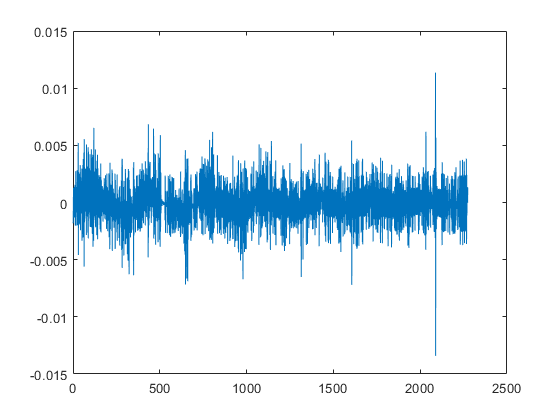

figure;
plot(err)

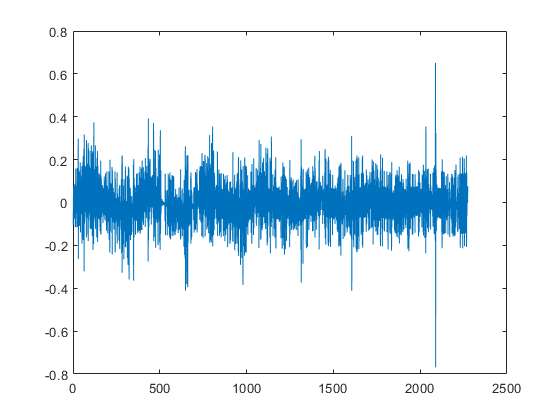


figure;
plot(err_degree)

layers = 1:4;
layers_test = zeros(length(layers), length(training_data_output));
for i=layers
    net = feedforwardnet(i, 'trainlm');
    net = train(net, x_train, y_train);

    y_net = net(x_train);
    layers_test(i, :) = y_net;
    perf = perform(net,y_train, y_net)
end

perf = 3.8506e-06

perf = 3.8419e-06

perf = 3.8511e-06

perf = 3.8247e-06

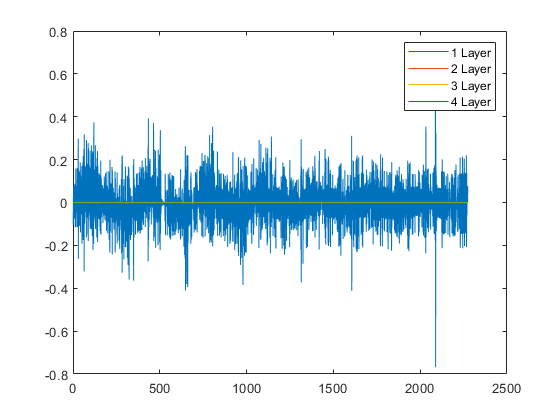

err = layers_test - y_net;
hold on
plot(err(1, :))
plot(err(2, :))
plot(err(3, :))
plot(err(4, :))
hold off
legend('1 Hidden Layer', '2 Hidden Layer', '3 Hidden Layer', '4 Hidden Layer')

y_test_begin_sample = 500;
y_test_end_sample = 1000;


training_data_input_1 = theta(y_begin_sample-2:y_end_sample-2)
training_data_input_2 = theta(y_begin_sample-1:y_end_sample-1)
training_data_output = theta(y_begin_sample:y_end_sample)